# Verify data collection timing for all the signals: ACT3D, EMG, METRIA, PPS

filepath = 'D:\usr\Ana Maria Acosta\OneDrive - Northwestern University\Data\TACS\Data';
partid = 'RTIS2001';
load(fullfile(filepath,partid,'7621\left',[partid '_setup.mat'])); %load setup file 

% function [dist,vel,timestart,timevelmax]=ComputeReachStart_NRSA(flpath,filename)

% function [dist,vel,timestart,timevelmax,timeend,timedistmax,distold]=ComputeReachStart_2021(actdata,metdata,setup,g)

## Load trial data

load(fullfile(filepath,partid,'7621\left\trial20'))
% data.daq={daqt,daqdata};
plot(data.daq{1},'o') % Plot the DAQ time vector
disp([max(data.daq{1}) length(data.daq{1}) data.daq{1}(1:10)'])

   1.0e+03 *

  Columns 1 through 7

    0.0050    5.0000         0    0.0000    0.0000    0.0000    0.0000

  Columns 8 through 12

    0.0000    0.0000    0.0000    0.0000    0.0000



% ACT3D time
% time=double(source.ScansAcquired)/myhandles.daq.sRate; % asks how many scans acquired 
% actdata(counter,:)=[time hpos' myhandles.robot.endEffectorPosition,...
plot(data.act(:,1),'o') % Plot the ACT3D time vector
disp([max(data.act(:,1)) length(data.act(:,1)) data.act(1:10,1)'])

  Columns 1 through 7

    5.0000  250.0000    0.0200    0.0400    0.0600    0.0800    0.1000

  Columns 8 through 12

    0.1200    0.1400    0.1600    0.1800    0.2000



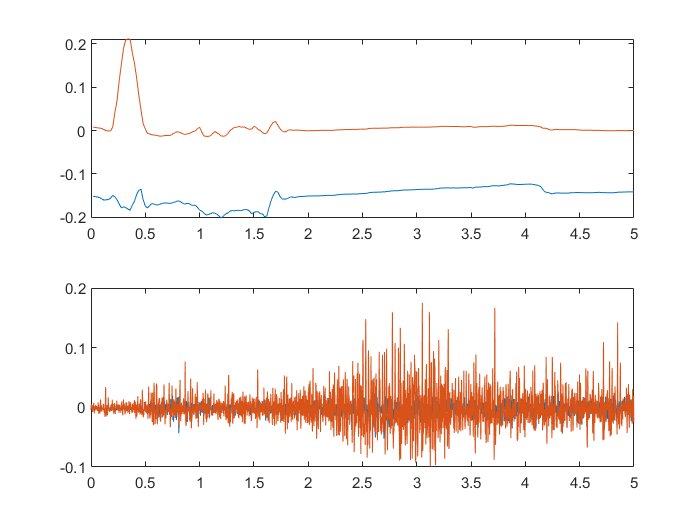

subplot(211),plot(data.act(:,1),data.act(:,2:3))
subplot(212),plot(data.daq{1},data.daq{2}(:,13:14))

actdata=data.act;
x= data.met;

%Use if plotting ACT3D data
% 
% Xpos = actdata(:,2);
% Ypos = actdata(:,3);
% Zpos = actdata(:,4);
% 
% Xvel = actdata(:,9);
% Yvel = actdata(:,10);
% Zvel = actdata(:,11);

## Loading in Metria Data

Sampling Rate for Metria is 89 HZ

%uncomment this section is using 

t = (x(:,2)-x(1,2))/89;

% x = metdata;
x(x==0)=NaN; %h Replace zeros with NaN
x = x(:,3:end); %omitting time and the camera series number
[nimag,nmark]=size(x);
nmark=(nmark)/8; 

% Creating Variables for Hand, Trunk Shoulder, Forearm, and Humerus
[ridx,cidx]=find(x==setup.markerid(4));
fidx =cidx(1)+1;
xfore=x(:,fidx:(fidx+6));  

[ridx,cidx]=find(x==setup.markerid(3));
aidx =cidx(1)+1;
xarm=x(:,aidx:(aidx+6)); %extracting humerus marker

[ridx,cidx]=find(x==setup.markerid(2));
sidx=cidx(1)+1;
xshoulder=x(:,sidx:(sidx+ 6)); % extracting shoulder marker

[ridx,cidx]=find(x==setup.markerid(1)); 
tidx=cidx(1)+1;
xtrunk=x(:,tidx:(tidx+6)); 
lcsfore=zeros(2*nimag,2);

## Computing 3rd MCP position from forearm

for i=1:nimag % loop through time points
    % For the 3rd metacarpal grabbing the forearm marker
    Tftom = quat2tform(circshift(xfore(i,4:7),1,2));
    Tftom(1:3,4) = xfore(i,1:3)';% Transformation matrix for forearm in time i
%     Tftom= [reshape(x(i,fidx+(2:13)),4,3)';[0 0 0 1]]; % Transformation matrix for forearm in time i
%      BLg=(Tftom)*setup.bl.lcs{4}(:,4);  %grabbing the XYZ point of the 3rd metacarpal in the LCS and
%        BLg = Tftom*(bl{1,4}(4,1:4))';
%       BLg=Tftom *[bl{4}(4,1:3) 1]'; From GetHandShoulderTrunkPosition8
 
      BLg=Tftom *setup.bl.lcs{1,4}(1:4,4) ; %changed from BL file 
      xhand(i,:)=BLg(1:3,1)'; % X Y Z of the BL in global cs and rows are time 
      lcsfore(2*i-1:2*i,:)=Tftom(1:2,1:2);
% for the acromion using the shoulder marker 
%     Tstom= reshape(x(i,sidx+(2:13)),4,3)'; % grabbing the HT of the shoulder marker 
%     Tstom = [Tstom;0 0 0 1]; 
%     BLg2=(Tstom) *setup.bl.lcs{2}(:,1);  %grabbing the XYZ point of the anterior acromion in the LCS
%     xshldr(i,:)=BLg2(1:3,1)'; % X Y Z of BL in the global frame and rows are time 
end

## Resampling Xhand

%xhand old is the original mnot resampled version
% [xhand2,t2] = resample(xhand,t,1000,10,89);
[xhand2,t2]=resampledata(xhand,t,100,89);

## Finding Distance and Vel -- Updated May 2021 for Metria Data

%using original data
% Xoold = nanmean(xhandold(1:50,1));
% Yoold = nanmean(xhandold(1:50,2)); 
% Zoold = nanmean(xhandold(1:50,3)); 
% 
% %using Resampled Data
% Xo = nanmean(xhand(1:50,1));
% Yo = nanmean(xhand(1:50,2)); 
% Zo = nanmean(xhand(1:50,3)); 
% 
% % %Computing Velocity from hand position
% % Xvel = diff(xhand(:,1));
% % Yvel = diff(xhand(:,2));
% % Zvel = diff(xhand(:,3));
% 
% % Xov = nanmean(Xvel(1:50));
% % Yov = nanmean(Yvel(1:50)); 
% % Zov = nanmean(Zvel(1:50)); 
% 
% dist = sqrt((xhand(:,1)-Xo).^2 +(xhand(:,2)-Yo).^2 + (xhand(:,3)-Zo).^2);
% distold =sqrt((xhandold(:,1)-Xoold).^2 +(xhandold(:,2)-Yoold).^2 + (xhandold(:,3)-Zoold).^2);
% distold = distold(:)-distold(1);
% 
% dist = dist(:)-dist(1); %offsetting so not starting above 0

% AMA - You want to compute the distance between the home target or the
% beggining of the trial and max reach.
dist=sqrt(sum(xhand'.^2));
dist=dist-mean(dist(1:10));

dist2=sqrt(sum(xhand2'.^2));
dist2=dist2-mean(dist2(1:10));

% Using function from AMA to compute Vel
vel = ddt(smo(dist,3),1/89);
[vel2,t2] = resampledata(vel,t,100,89);
subplot(211),plot(t,xhand,t2,xhand2,'-')
subplot(212),yyaxis left; plot(t,dist,t2,dist2); yyaxis right; plot(t,vel,t2,vel2)
return

% vel = sqrt((Xvel-Xov).^2 +(Yvel-Yov).^2 + (Zvel-Zov).^2);

% t = length(vel)/ 50; % time in seconds sampling rate of metria? 250 samples in 5 seconds
% t = 0:.02:5;
% t = t(2:end);


idx=zeros(1,4); % creating variable with the indices of vel and distance for ACT3D
 idx(1) = find(dist>50,1); % start reaching 

[vpks,vlocs] = findpeaks(vel(idx(1):end)); vlocs=vlocs+idx(1)-1;
[~,idx(2)] = max(vel); %max vel

idx(2)=vlocs(length(vlocs/2)); %finding the first peak as the max vel

% maxvel =max(vel);
% idx(2)= find(vel==maxvel);


%Yielded odd results 
% [dpks,dlocs] = findpeaks(dist(idx(1):end)); dlocs=dlocs+idx(1)-1;
% % [~,idx(3)] = max(dist(idx(2)+1:end)); % idx3 max reach
% idx(3)=dlocs(1); %Finding first peak of max distance
% rdist=dpks(1);

%Finding Max dist
maxdist= max(dist);
idx(3)= find(dist==maxdist);

%idx(4)=idx(3)+6; % Mark end of movement 1s after max velocity

%sampling rate of act 3d - 50 HZ

% start time in seconds 
timestart = idx(1)*(1/1000);% divide by sampling rate
timevelmax = idx(2)*(1/1000); % time when max velocity
timedistmax = idx(3) *(1/1000); %when at max dist
% timebefore = timestart-.05; %time 50 ms prior to start of reach
timebefore =1;
timeend = timedistmax+2;
%ibefore = ceil(timebefore*50); 
%timeend = idx(4)*(1/1000);

## Plotting Data

Muscles = {'LES','RES','LRA','RRA','LEO','REO','LIO','RIO','UT','MT','LD','PM','BIC','TRI','IDEL'}

figure()
subplot(3,3,2)
%ax = axes('position',[0.12,0.75,0.75,0.22]);
%plot(t(1:50),dist(1:50))
 plot(t,dist)
hold on
plot(t,vel) 
%  plot(timestart,dist(idx(1)),'-o') %reach start
%  plot(timevelmax,vel(idx(2)),'-o') % Max velocity
%  plot(timebefore,dist(ibefore),'-o') %Time before
%  plot(timedistmax ,dist(idx(3)),'-o') %max distance
%  plot(timeend,dist(idx(4)),'-o') %end of reach

p1 = line('Color','b','Xdata',[timestart timestart],'Ydata',[-500 500], 'LineWidth',.5); % start reach
p2= line('Color','m','Xdata',[timevelmax timevelmax],'Ydata',[-500 500],'LineWidth',.5); % max vel
p3= line('Color','c','Xdata',[timedistmax timedistmax],'Ydata',[-500 500],'LineWidth',.5); %max, dist
p4= line('Color','g','Xdata',[timebefore timebefore],'Ydata',[-500 500],'LineWidth',.5); %time prior
p5= line('Color','r','Xdata',[timeend timeend],'Ydata',[-500 500],'LineWidth',.5);

% co=get(lax1,'ColorOrder');
% set(lax1,'ColorOrder',co(end-1:-1:1,:))

xlim([0.5 5])

xlabel('time in seconds')
ylabel('Distance/ Velocity') 
legend('Distance', 'Velocity','Start Reach','Max Velocity','Max Dist','Time Prior','Time End')
title(Muscles(g))


function [y,ty]=resampledata(x,t,fs,fsnew)
% compute slope and offset (y = a1 x + a2)
[nr,nc]=size(x);
for i=1:nc
    a(1) = (x(end,i)-x(1,i)) / (t(end)-t(1));
    a(2) = x(1,i);
    
    % detrend the signal
    xdetrend = x(:,i) - polyval(a,t);
    [ydetrend,ty] = resample(xdetrend,t,fsnew,10,fs);
    
    if i==1, y=zeros(length(ty),nc); end
    
    y(:,i) = ydetrend + polyval(a,ty);
end
end

% end